%% fase experimental
X = 0.5; %Pressão pretendida(bar)
K = [5 30 50 70 90 120]; % valores para o compensador proporcional
t = 1:200; % 200 valores para a pressão corresponde a 60s de análise (período de amostragem = 0.3s)
Ek = zeros(length(K),1); % array para o erro associado a cada valor de K
Yk = zeros(length(K),200); % array para as pressões
Vk = zeros(length(K),200); % array para as diferenças de potencial aplicadas ao compressor
%Relatório – RT030 - Sistema de Controlo de Pressão de Ar
for j = 1:length(K)
KinTest = K(j)
ErrorCode = RT030_SetCompressorVoltage(0);
P = RT030_GetPressure();
while(P > 0.0001)
P = RT030_GetPressure();
end
Y = zeros(1,200);
V = zeros(1,200);
for i = 1:200
Y(i) = RT030_GetPressure(); % sinal de saida, Y(s)
E = X - Y(i); % sinal de erro, E(s)
V(i) = K(j)*E; % tensão aplicada ao motor, V(s)
% não é necessário limitar a tensão entre [0 5]V, pois o sistema já o faz
ErrorCode = RT030_SetCompressorVoltage(V(i));
pause(0.3);
end
ErroK = (abs(X-mean(Y(180:200)))/X)*100;
ErrorCode = RT030_SetCompressorVoltage(0);
Yk(j,:) = Y;
Ek(j) = E;
Vk(j,:) = V;
end

KinTest = 5

KinTest = 30

KinTest = 50

KinTest = 70

KinTest = 90

KinTest = 120

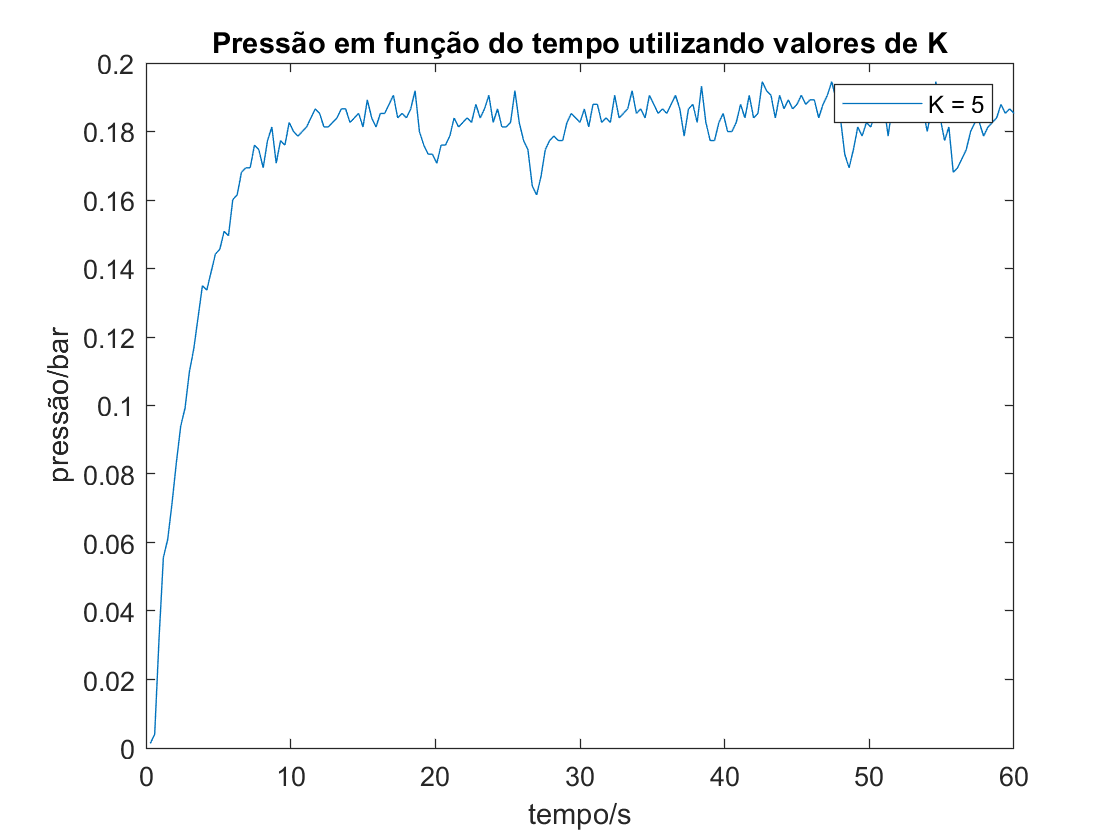

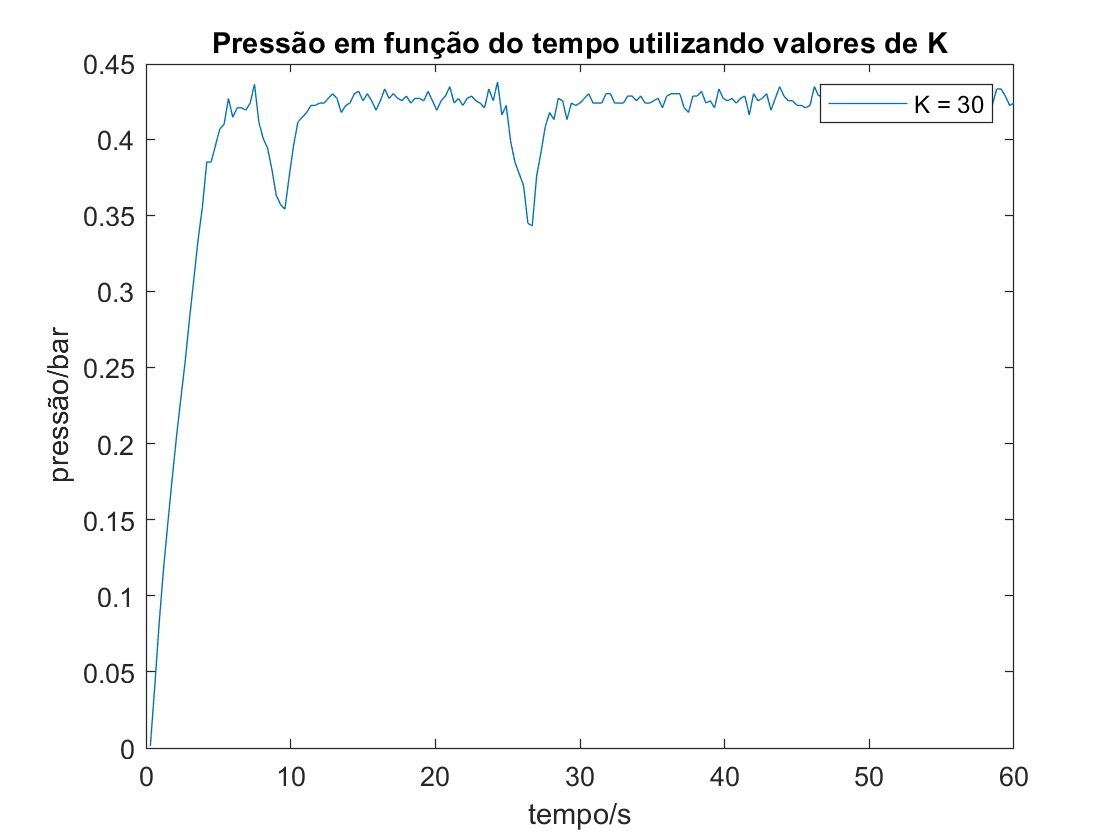

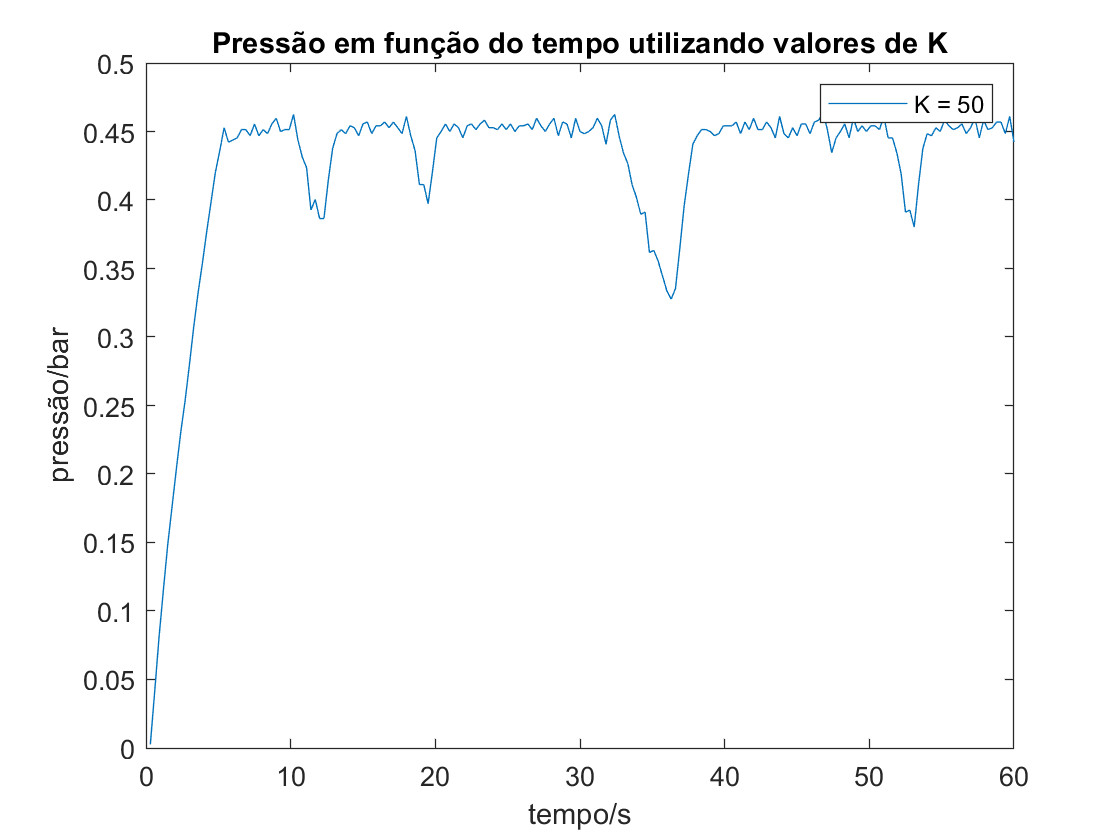

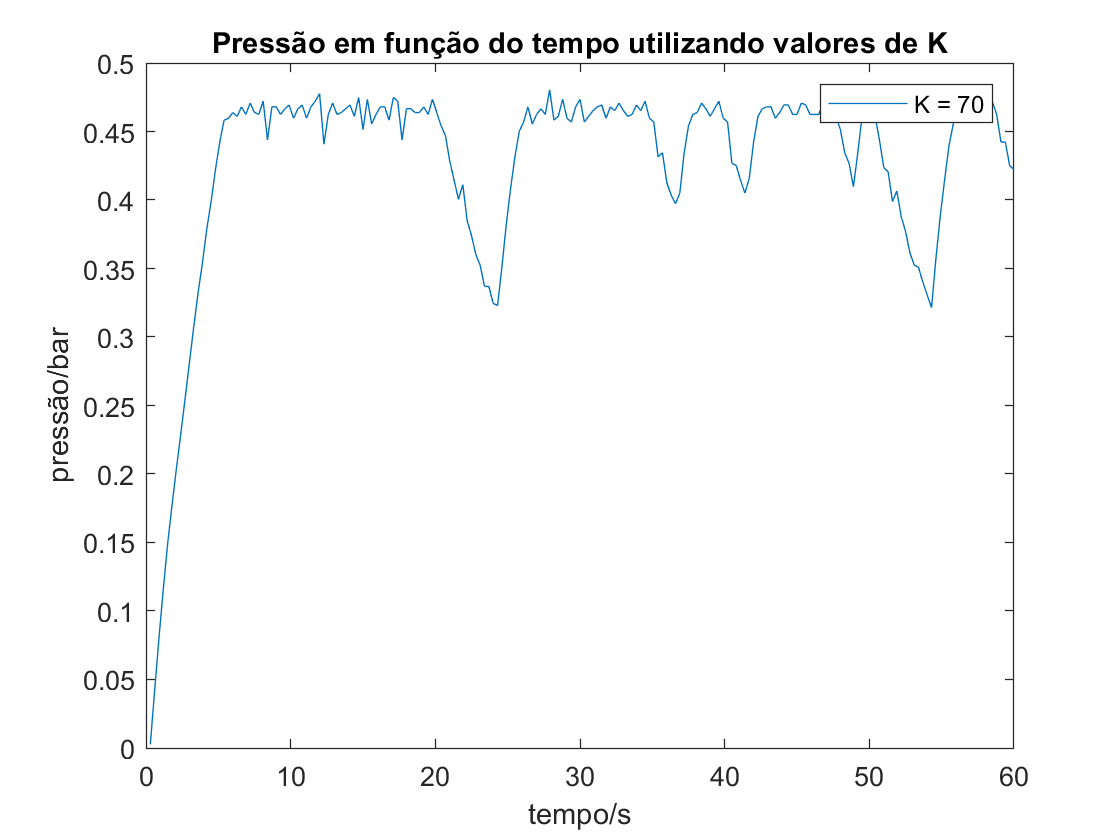

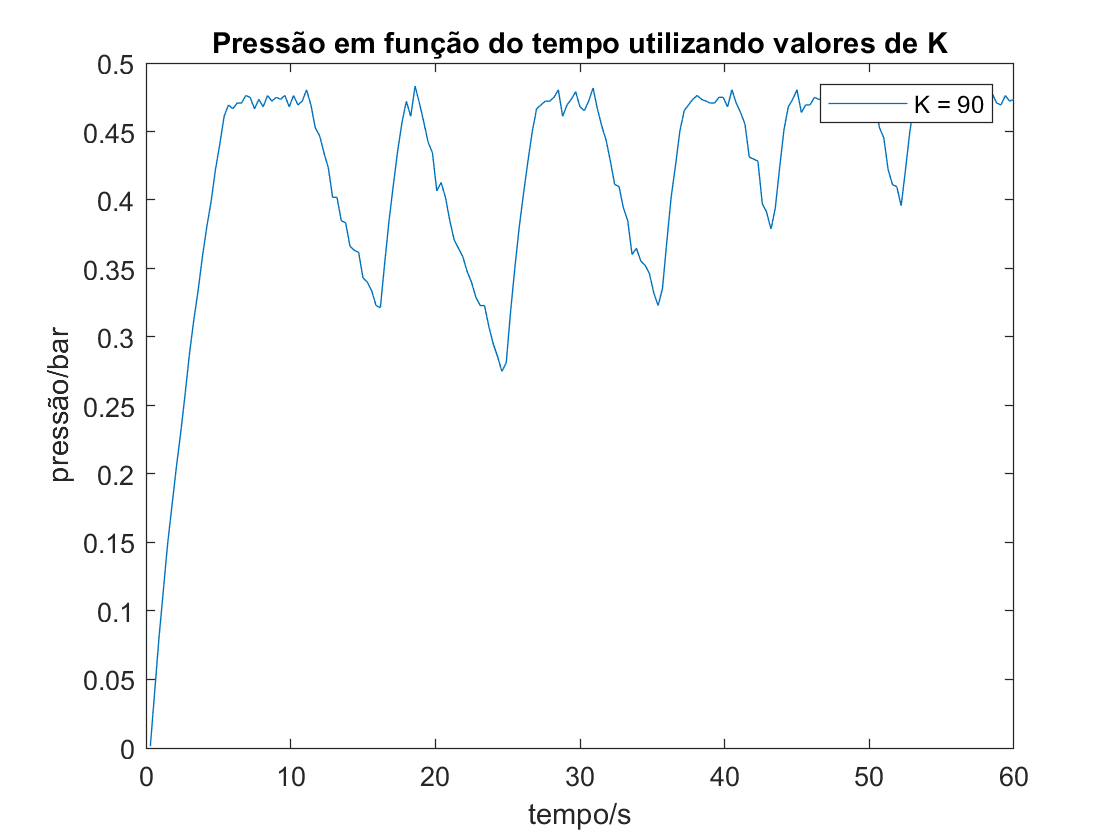

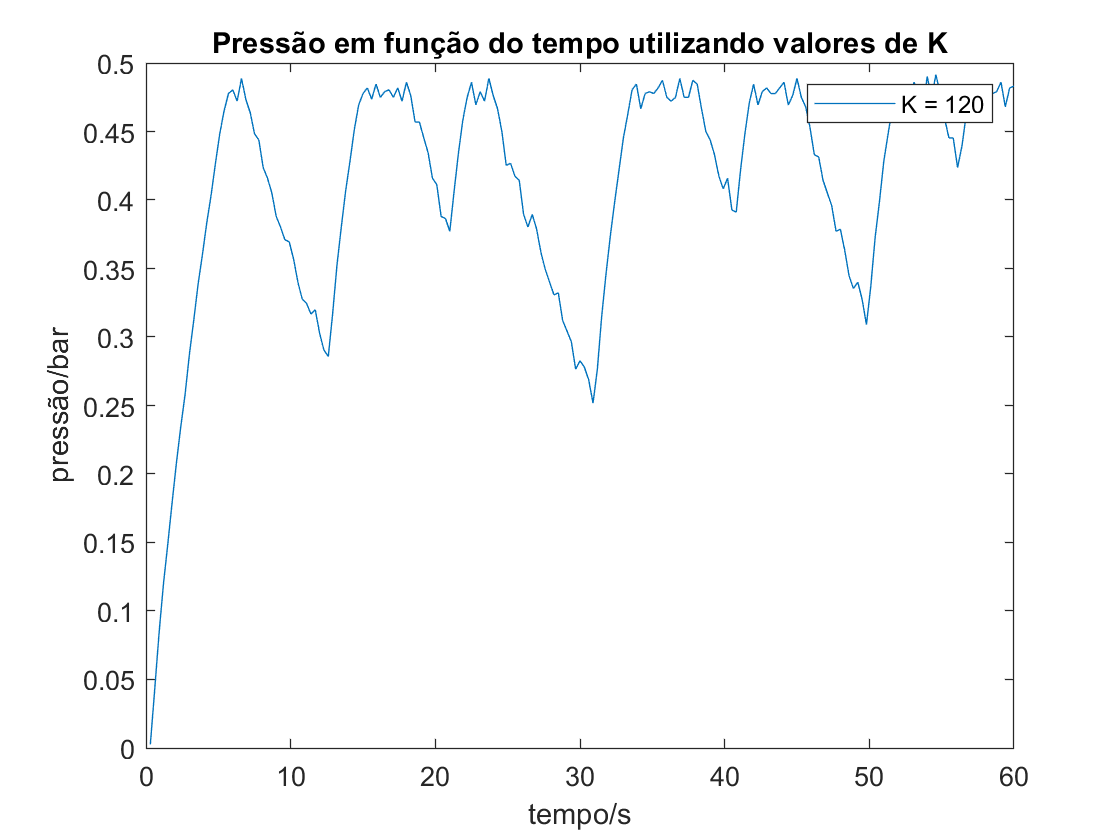

%
%% analise de dados
close all;
%Visualização gráfica pressão em função do tempo
%A variável t é multiplicada por 0.3 por corresponder ao período de
%amostragem de cada valor de pressão
for j = 1:length(K)
figure(j)
plot(t*0.3, Yk(j,t)),title("Pressão em função do tempo utilizando valores de K"),xlabel("tempo/s"),ylabel("pressão/bar")
legend(['K = ',num2str(K(j))])
end

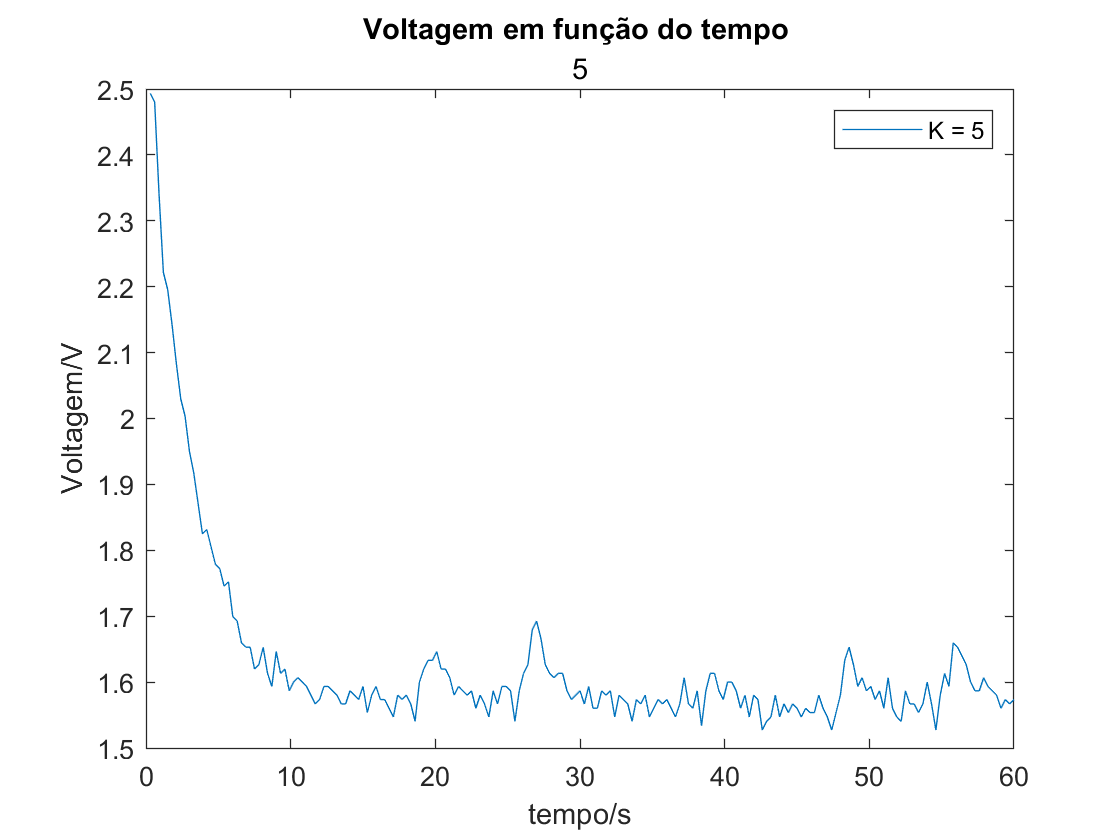

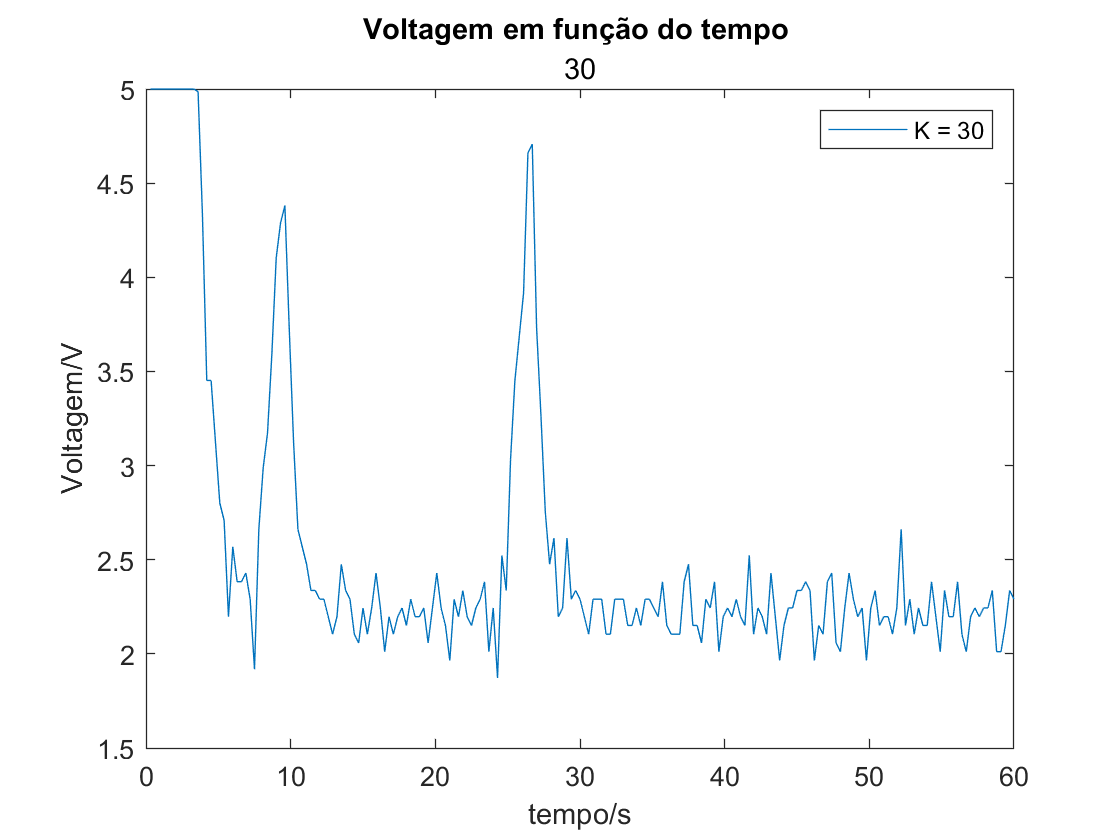

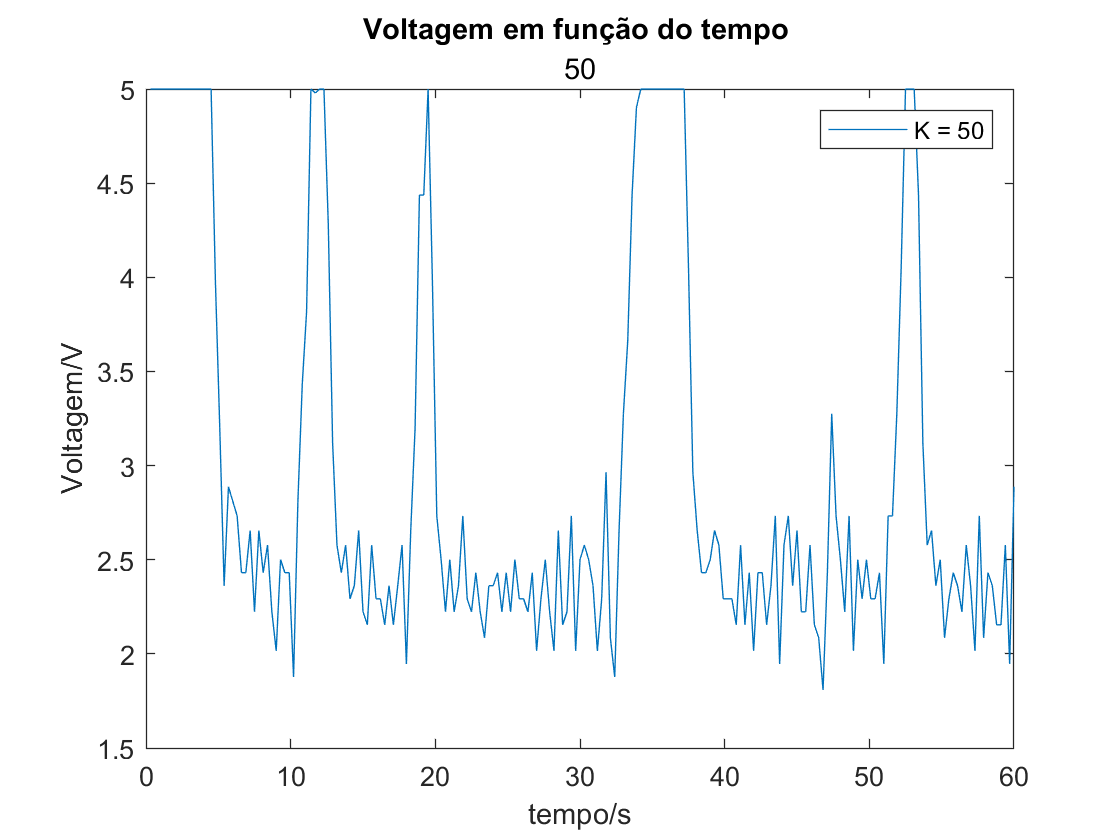

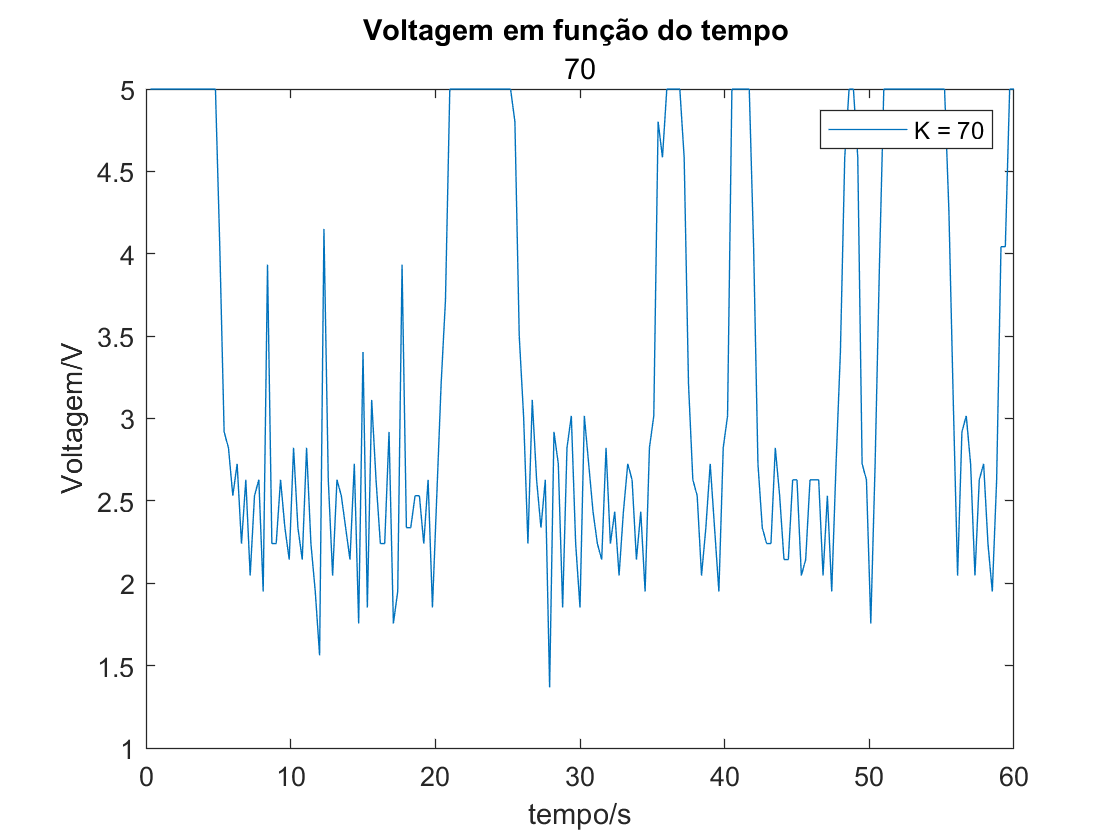

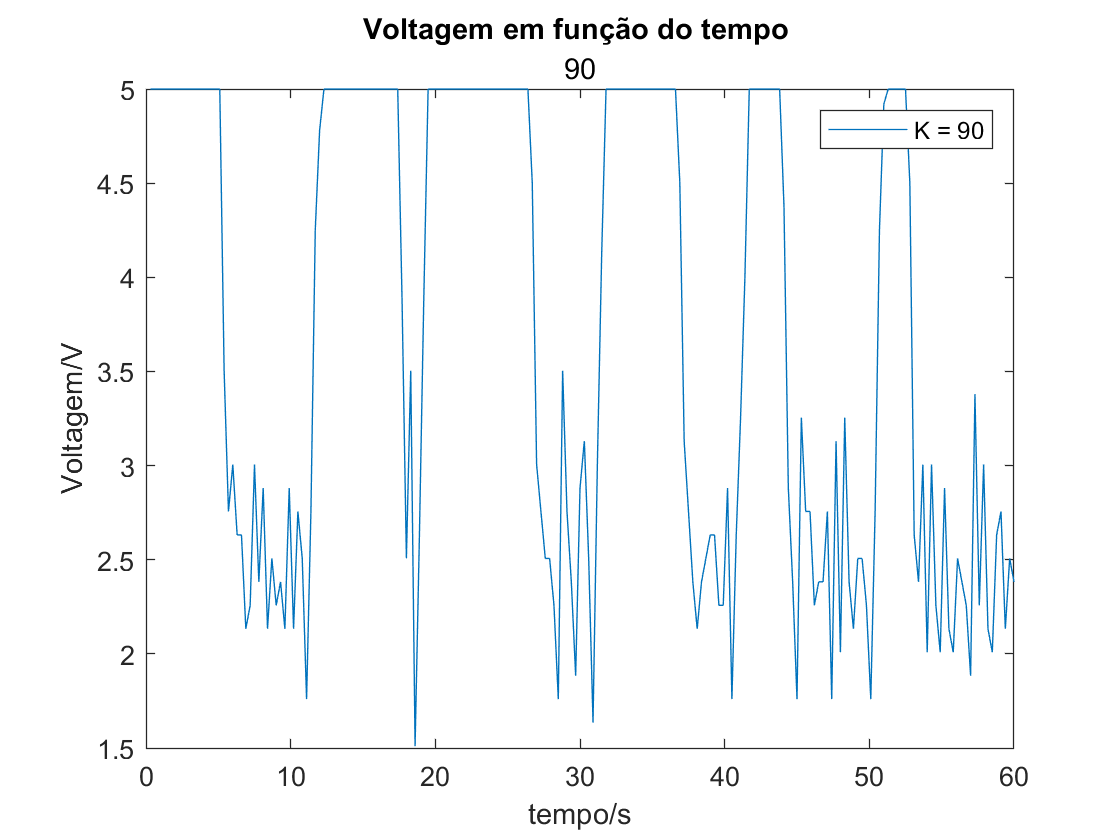

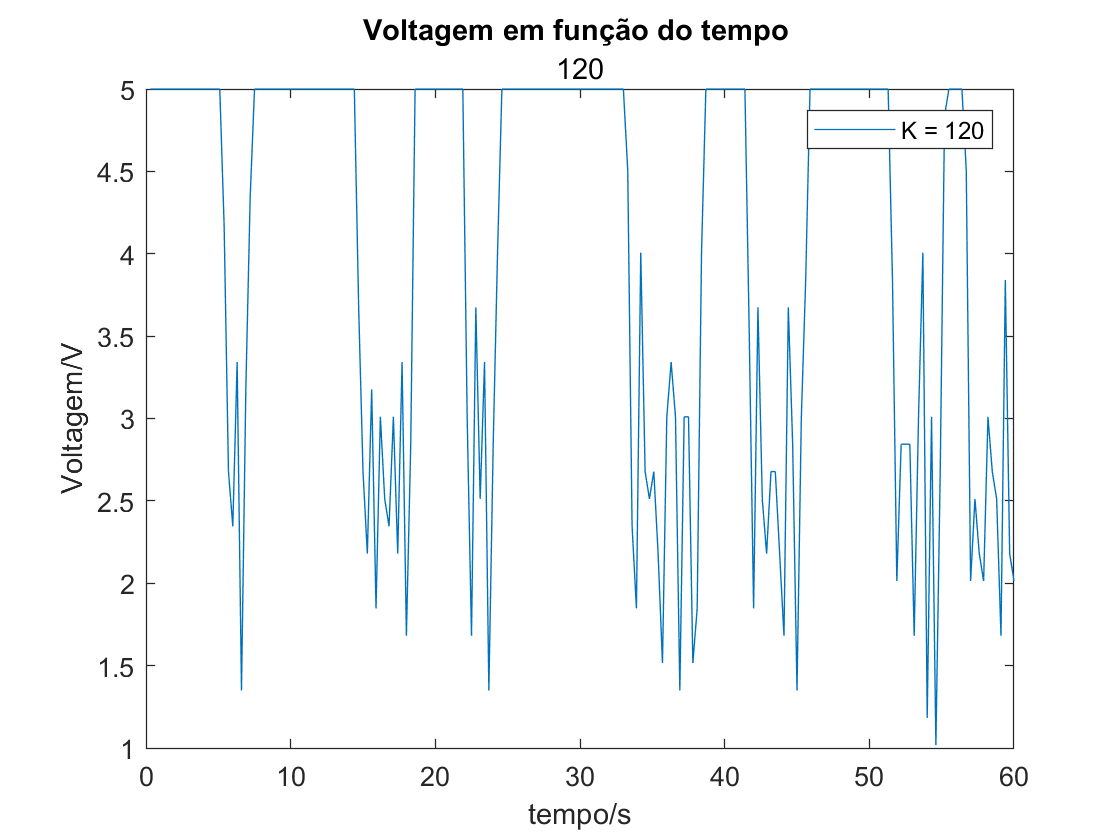

%Visualização gráfica dos valores de tensão aplicadas ao compressor
%Os valores fora do intervalo [0 5]v são colocados dentro do limite
%mais próximo
for q = length(K)+1:2*length(K)
figure(q)
Vlim = zeros(1, 200);
for r = 1:length(t)
if (Vk(q-length(K),r)<0)
Vlim(r) = 0;
elseif (Vk(q-length(K),r)>5)
Vlim(r) = 5;
else
Vlim(r) = Vk(q-length(K),r);
end
end
plot(t*0.3, Vlim(t)),title("Voltagem em função do tempo K=",K(q-j)),xlabel("tempo/s"),ylabel("Voltagem/V")
legend(['K = ',num2str(K(q-j))])
end

legend show